Load and prepare images

cow_data = ...
    imageDatastore("full_dataset", "IncludeSubfolders", true, "LabelSource", "foldernames");

[cowTrain, cowTest] = splitEachLabel(cow_data, 0.7, 'randomized');


Create bag of visual features

bag = bagOfFeatures(cow_data);

Creating Bag-Of-Features.
-------------------------
* Image category 1: cow_0
* Image category 2: cow_1
* Image category 3: cow_2
* Image category 4: cow_3
* Image category 5: cow_4
* Image category 6: cow_5
* Image category 7: cow_6
* Image category 8: cow_7
* Image category 9: cow_8
* Image category 10: cow_9
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 500 images...done. Extracted 2048000 features.

* Keeping 80 percent of the strongest features from each category.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 1638400
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 26/100 iterations (~5.28 seconds/iteration)...converged in 26 iterations.

* Finished creating Bag-Of-Features



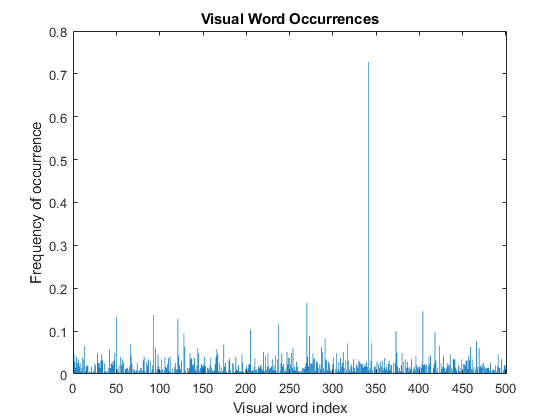


% visual word occurrences
img = readimage(cow_data, 1);
featureVector = encode(bag, img);

figure 
bar(featureVector)
title("Visual Word Occurrences")
xlabel("Visual word index")
ylabel("Frequency of occurrence")

Train image category classifier

categoryClassifier = trainImageCategoryClassifier(cowTrain, bag);

Training an image category classifier for 10 categories.
--------------------------------------------------------
* Category 1: cow_0
* Category 2: cow_1
* Category 3: cow_2
* Category 4: cow_3
* Category 5: cow_4
* Category 6: cow_5
* Category 7: cow_6
* Category 8: cow_7
* Category 9: cow_8
* Category 10: cow_9

* Encoding features for 350 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




confMatrix = evaluate(categoryClassifier, cowTrain);

Evaluating image category classifier for 10 categories.
-------------------------------------------------------

* Category 1: cow_0
* Category 2: cow_1
* Category 3: cow_2
* Category 4: cow_3
* Category 5: cow_4
* Category 6: cow_5
* Category 7: cow_6
* Category 8: cow_7
* Category 9: cow_8
* Category 10: cow_9

* Evaluating 350 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                              PREDICTED
KNOWN    | cow_0   cow_1   cow_2   cow_3   cow_4   cow_5   cow_6   cow_7   cow_8   cow_9   
-------------------------------------------------------------------------------------------
cow_0    | 1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_1    | 0.00    1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_2    | 0.00    0.00    1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_3    | 0.00    0.00    0.00    1.00    0.00

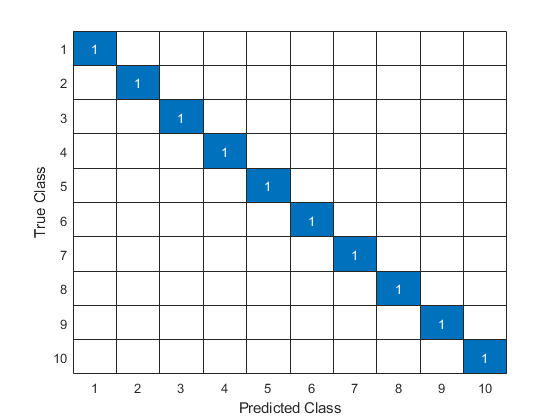


figure
confusionchart(confMatrix)


confMatrix = evaluate(categoryClassifier, cowTest);

Evaluating image category classifier for 10 categories.
-------------------------------------------------------

* Category 1: cow_0
* Category 2: cow_1
* Category 3: cow_2
* Category 4: cow_3
* Category 5: cow_4
* Category 6: cow_5
* Category 7: cow_6
* Category 8: cow_7
* Category 9: cow_8
* Category 10: cow_9

* Evaluating 150 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                              PREDICTED
KNOWN    | cow_0   cow_1   cow_2   cow_3   cow_4   cow_5   cow_6   cow_7   cow_8   cow_9   
-------------------------------------------------------------------------------------------
cow_0    | 1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_1    | 0.00    1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_2    | 0.00    0.00    1.00    0.00    0.00    0.00    0.00    0.00    0.00    0.00    
cow_3    | 0.00    0.00    0.00    1.00    0.00


figure
confusionchart(confMatrix)